M = randn(50,500)

M =    -0.7493    1.1608   -1.0636   -1.9351   -0.4794    1.4816   -0.1984   -0.2438   -0.0434   -0.6686    0.9896   -1.4463    0.1542    0.6437    0.1412   -0.1980   -0.6357   -2.4135   -0.6504   -0.7325    0.3562   -0.5678    0.1654   -0.1311   -0.1170    0.0273    0.1029    0.9085    0.3167   -0.9033    0.6913    0.2633   -0.3627   -0.6856    0.5425    1.2719   -1.4840    0.6027   -1.5689    0.3484    1.6771    0.9807    1.2578    0.0302   -0.3895   -0.0040   -0.0801   -0.3206    0.2476   -0.2184
   -1.6017   -0.6750    0.4235    0.8473   -0.3479    1.5473   -0.2346   -1.1862    0.2398   -1.0754   -0.3576   -0.8495   -1.2414   -1.4855   -0.4864   -0.2201    0.6490    0.6038    0.2266   -0.0283   -1.7585    0.4248   -0.6326    0.4072   -0.1197   -1.2053    1.2559   -0.5265   -0.3762    0.4860    0.3771    1.0125    1.2287    0.1865    1.0683   -0.0213   -1.7176    0.4605    1.4157    1.0750   -0.5515   -0.3510   -1.3623    0.3826    0.1998    0.9451    0.1661    0.1965    0.9345    0


mu = mean(M);
M_mean = M - mu;
cov_M = cov(M_mean);

[eig_vec,eig_val] = eigs(cov_M);

% Sort eigenvalues in decreasing order
[sorted_eig_vals, indices] = sort(diag(eig_val), 'descend');
sorted_eig_vecs = eig_vec(:, indices);

E = sorted_eig_vecs'

E =     0.0199   -0.0211    0.0479    0.0365    0.0325   -0.0224    0.0814    0.0350   -0.0182    0.0840   -0.0664   -0.0044    0.0595    0.0359    0.0334   -0.0288    0.0438    0.0034   -0.0805    0.0835   -0.0075    0.0010   -0.0501    0.0033    0.0226    0.0125   -0.0735    0.0101    0.0451   -0.0272   -0.0390    0.0546   -0.0336   -0.0283   -0.0863   -0.0580    0.0641   -0.0157    0.0542   -0.0257    0.0099    0.0776    0.0268    0.0349   -0.0540   -0.0372    0.0413   -0.0713    0.0325    0.0075
   -0.0416    0.0420    0.0354   -0.0071   -0.0473    0.0004    0.0183    0.0740    0.0214    0.0529    0.0214   -0.0531    0.0094    0.0474    0.0293   -0.0076    0.0666   -0.0447    0.0079   -0.0020   -0.0175   -0.0178    0.0289   -0.0106   -0.0973    0.0585   -0.0958    0.0472    0.0038    0.0120   -0.0002   -0.0320   -0.0540    0.0384   -0.0110    0.0537    0.0797    0.0123   -0.0745   -0.1236   -0.0216    0.0472    0.0263   -0.0368    0.0183    0.0162   -0.0074    0.0275   -0.0202   -0

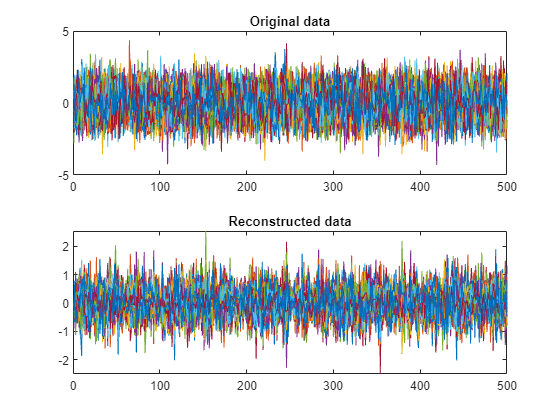

ET = E';
X_reduced = M_mean * ET;
X_reconstructed = X_reduced * E + mu;

rmse(b) = sqrt( mean( mean((X_reconstructed - M).^2)));

figure;
subplot(2, 1, 1);
plot(M');
title('Original data');
subplot(2, 1, 2);
plot(X_reconstructed');
title('Reconstructed data');


%rmse = sqrt( mean( mean((M - M_1).^2)))
%pca()